# Extra Credit - Finding Probability of Failure

In this problem, you are asked to find the probability of failure of the truss-crane system. There are two functions defined for you. `find_forces(Px, P, x)` and `check_failure(Forces)`*. *Your task is to fill in those functions such that `find_forces(Px, P, x)` correctly calculates each force for each member and `check_failure(Forces)` correctly checks to see if any member have failed. Please remember that you need to be within 1% of the actual answer for full credits. 

## Failure Probability

The code below runs N many simulations and checks if the system has failed at the each simulation. If it did, it adds +1 to the number of failures. If you correctly define `find_forces(Px, P, x)` and `check_failure(Forces)`*, *this code snippet should display the correct percentage. You do not need to change anything in this cell. 

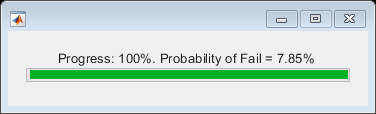

%%%%%%%%%%%%%%% NO NEED TO CHANGE %%%%%%%%%%%%%%%%%%
N=50000; %number of simulations
Total_Fails=0;
f = waitbar(0, 'Starting');
for i=1:N %run N many simulations
    
    P=normrnd(80,15); %randomly sample a P (kN)
    Px=normrnd(0,20); %randomly sample a Px (kN)
    x = unifrnd(0,4); %randomly sample an x (m)

    Forces=find_forces(Px, P, x); %find the forces for given P,Px,x
    fail=check_failure(Forces);   %check to see if failed
    Total_Fails=Total_Fails+fail; %if failed, increment Total_Fails by 1


    if rem(i,N/5)==0 %display the progress to user
        waitbar(i/N, f, sprintf('Progress: %d%%', floor(i/N*100)));
    end
    
end
waitbar(i/N, f, sprintf('Progress: %d%%. Probability of Fail = %.2f%% ', (floor(i/N*100)), Total_Fails/N*100));

fprintf('Failure Probability is %.2f%% \n', Total_Fails/N*100);

Failure Probability is 7.85% 


### Test Cell

You can use this cell to see if your functions work correctly before running them in the large loop. 

`ExampleForces`** should give you a dictionary of all member forces correctly ** 

`ExampleFail`** should correctly return a 1 if the system fails and 0 if it does not**

ExampleForces=find_forces(80, -20, 1)


ExampleForces =

  dictionary (string ⟼ double) with 15 entries:

    "HJ"   ⟼ -20.6155
    "DI"   ⟼ -61.8466
    "Mmax" ⟼ -15
    "GH"   ⟼ -5
    "FH"   ⟼ 20.0000
    "FG"   ⟼ 7.0711
    "EG"   ⟼ -5
    "CE"   ⟼ -5
    "EF"   ⟼ 0
    "CF"   ⟼ -7.0711
    "DF"   ⟼ 30.0000
    "CD"   ⟼ -15
    "BD"   ⟼ 90.0000
    "BC"   ⟼ 28.2843
    "AC"   ⟼ -30




ExampleFail=check_failure(ExampleForces)

ExampleFail = 0

## Defining Functions

You can define functions here. 

For` find_forces(Px, P, x)`, please remember that by default, MATLAB works in radians not degrees. 

For `check_failure(Forces)`, please remember that you care about the absolute value of a member force. meaning that you should check if the absolute value of the member force is larger than the limit. You may need a loop to check each member and see if they fail. Please remember that if a member fails, you should just return 0. You do not need to keep searching the other members (you can use the `break` command)

function memberForces = find_forces(Px, P, x)
    %calculate forces for this system given Px, P, and x
    %order is HJ, DI, Mmax, GH, FH, FG, EG, CE, EF, CF, DF, CD, BD, BC, AC
    
    %%%%%%%%%%% YOU CAN FILL IN THIS SECTION%%%%%%%%%%%%%%%%%%%
    %you need to find the forces in each member. 
    a = pi/4; % angle of each truss member from the x (or y) axis
    L=4; %length of beam (m)
    theta = atan(Px/P);
    HJ = P*x/L/cos(theta);
    DI = (P*L - P*x)/L/cos(theta);
    Mmax = DI*cos(theta)*x;
    GH = HJ*cos(theta);
    FH = HJ*sin(theta);
    FG = -GH/sin(a);
    EG = -FG*sin(a);
    CE = EG;
    EF = 0*EG;
    CF = -FG;
    DF = FH + FG*sin(a) - CF*sin(a);
    CD = DI*cos(theta);
    BD = DF + DI*sin(theta);
    BC = -(CD + CF*sin(a))/sin(a);
    AC = CE + CF*sin(a) - BC*sin(a);
    %%%%%%%%%%%%%%% DO NOT CHANGE PAST HERE %%%%%%%%%%%%%%%%%%%%

    % Create a dictionary to hold all member forces
    names = ["HJ", "DI", "Mmax", "GH", "FH", "FG", "EG", "CE", "EF", "CF", "DF", "CD", "BD", "BC", "AC"]; %member names
    values = [HJ, DI, Mmax, GH, FH, FG, EG, CE, EF, CF, DF, CD, BD, BC, AC]; %forces
    memberForces = dictionary(names, values); %define a dictionary
end

function fail=check_failure(Forces)
    
    Members = ["HJ" "DI" "Mmax" "GH" "FH" "FG" "EG" "CE" "EF" "CF" "DF" "CD" "BD" "BC" "AC"]; %member names
    Limits=[147, 147, 170,  90,  90, 123,  90,  90,  10, 123, 170, 90, 170, 236, 330]; %limits
    Member_Limits = dictionary(Members,Limits); %define a dictionary
    fail=0; %assume no failure by default. Change to 1 if you find failure and break function
    
    %%%%%%%%%%% YOU CAN FILL IN THIS SECTION%%%%%%%%%%%%%%%%%%%
    %You need to loop through each member and check if that member fails
    for j=1:length(Members) %check for failure
        if abs(Forces(Members(j)))>Member_Limits(Members(j))
            fail=1;
            break
        end
    end
    %%%%%%%%%%%%%%% DO NOT CHANGE PAST HERE %%%%%%%%%%%%%%%%%%%%
end